姓名：莊璧如  學號：111321534

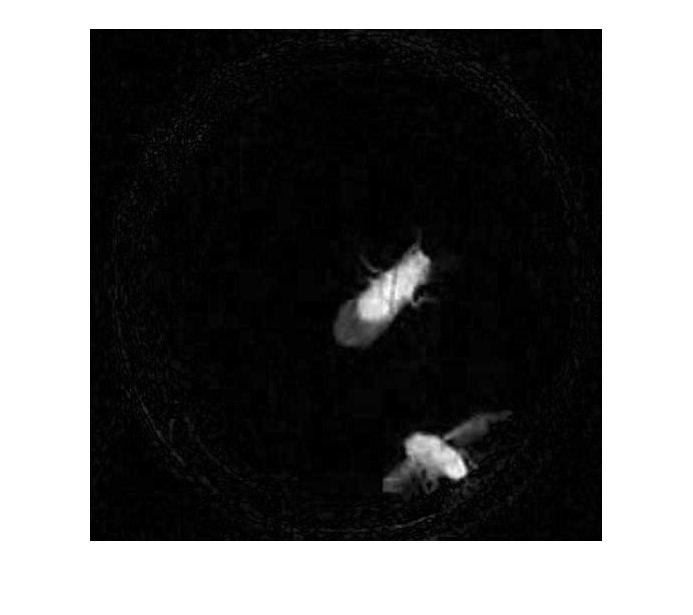

v=VideoReader('flyman512x512.avi');
video = readFrame(v);
i=0;
bg=imread('flymanBG.jpg');
bg=rgb2gray(bg);
while hasFrame(v)
    video = readFrame(v);
    video = rgb2gray(video);
    video=double(video);
    bg=double(bg);
    g=video-bg;
    g=abs(g);
    imshow((255+g)/2,[]), axis square
    drawnow
    i=i+1;
end


% while hasFrame(k)
%     bg = readFrame(k);
%     bg = rgb2gray(bg);
%     image(bg), axis square
%     drawnow
%     i=i+1;
% end      

%g=(g+255)/2;
% g=(g-min(g))*255./max(g)
% image(uint8(abs(g)));

ex2 Image averaging

r=imread('Fig3.30(a).jpg');
r=double(r);
i=0;
while (i<16) 
    t=randn(size(r));
    r=t+r;
    i=i+1;
    imshow(r,[]);
end
r=r/16
imshow(r,[])
title('r/16')

ex3

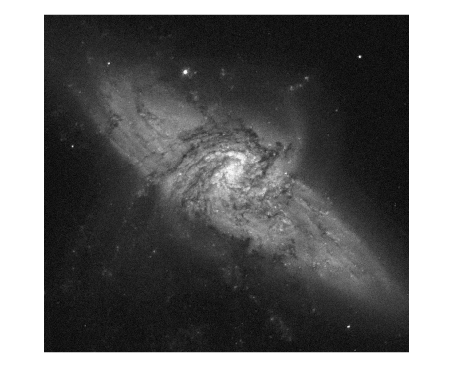

p=imread('pout.tif');

ret=myhist(p);

r =     1.7361    1.9685    2.0517    2.3456    1.5352    1.4896    1.6178    2.1862    1.6789    1.9531    1.8149    1.9920    1.7260    1.8508    1.6818    2.2777    1.3606    1.9178    1.5388    2.1449    2.1731    2.1193    1.5308    2.2160    1.6712    2.0395    2.7410    2.1800    2.0942    1.9454    2.2700    1.6168    2.4093    2.1684    1.4729    1.7545    1.9465    1.6044    1.7053    2.5581    1.7789    2.0895    1.5058    1.6921    1.5157    2.1110    1.3077    1.7410    1.4241    1.7063
    2.4772    1.8977    2.0188    1.4334    1.7607    1.5039    1.6849    1.7468    1.7443    1.5794    1.8781    1.3799    2.0945    1.7058    1.4203    1.5982    2.2767    1.6232    2.4591    2.1583    2.0474    2.2507    1.6513    2.1480    2.0452    2.5464    1.7580    2.0193    2.2096    2.4209    2.1968    1.8772    1.9495    1.5171    1.6640    2.0732    2.0433    2.3167    2.0780    1.8823    1.4608    1.7496    1.7170    1.6001    1.8993    2.0550    1.9506    1.8925    1.6125    1

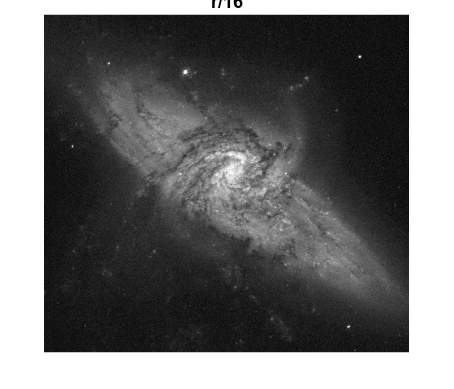

bar(ret);


ex4

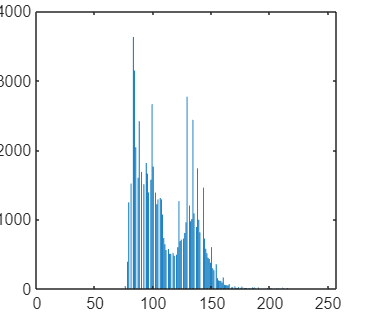

b1=imread('Fig3.15(a)1top.jpg');
[ph1, t1]=histeq(b1); % ph: equalized image, t: transformation 
plot(t1), title('transform functionb1');
figure, imshow(ph1)
b2=imread('Fig3.15(a)2.jpg');
[ph2, t2]=histeq(b2); % ph: equalized image, t: transformation 

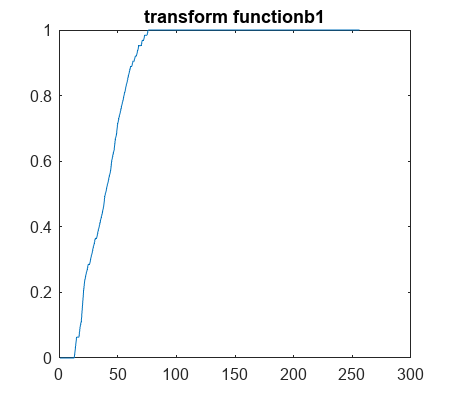

plot(t2), title('transform functionb2');
figure, imshow(ph2)
b3=imread('Fig3.15(a)3.jpg');
[ph3, t3]=histeq(b3); % ph: equalized image, t: transformation 
plot(t3), title('transform functionb3');

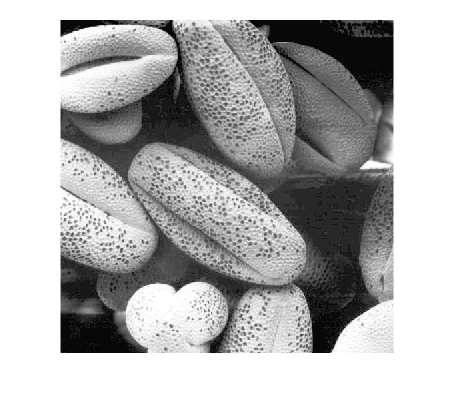

figure, imshow(ph3)

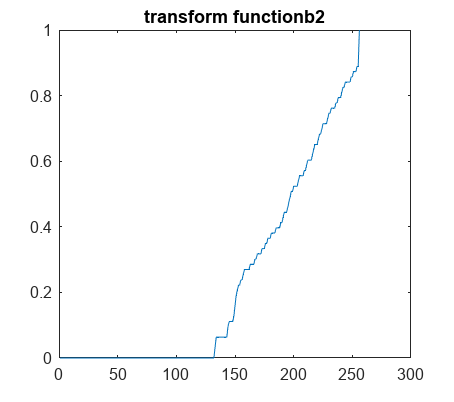

function ret=myhist(I)
    ret = zeros(256,1); % initialize histogram vector
    [row, col]=size(I);

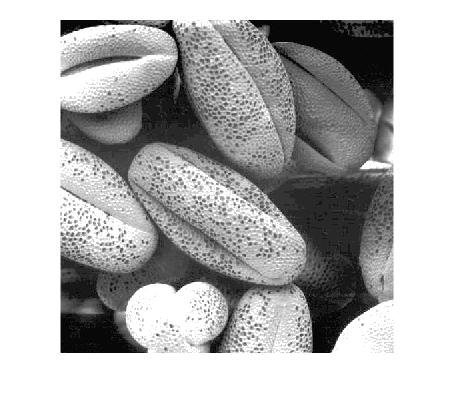

    for i=1:row

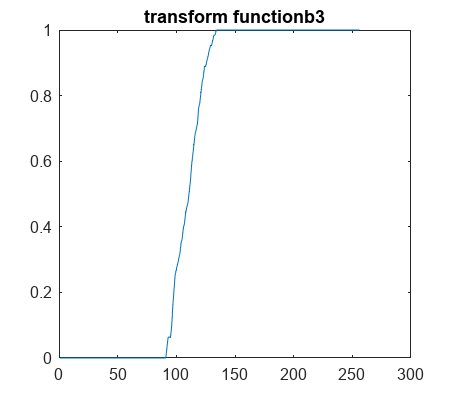

   
        for j=1:col
            ret(I(i,j)+1)=ret(I(i,j)+1)+1;

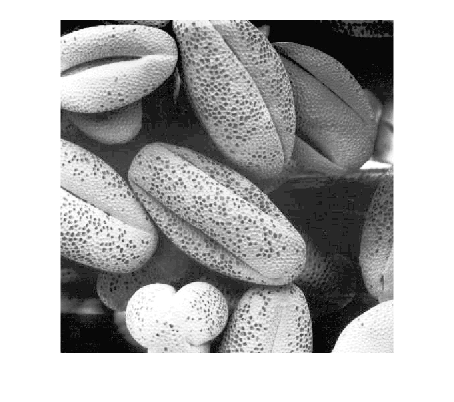

        end

    end
    end 